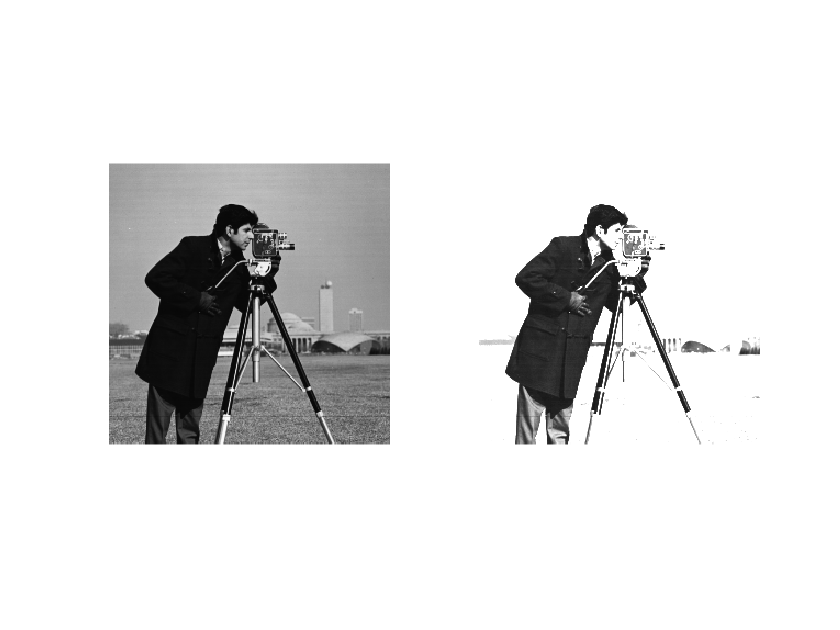

h =   Image - 属性:

           CData: [256×256 uint8]
    CDataMapping: 'scaled'

  显示 所有属性


i=imread('cameraman.tif');
figure
subplot(121);imshow(i);subplot(122);h=imshow(i,[0 80])

clear

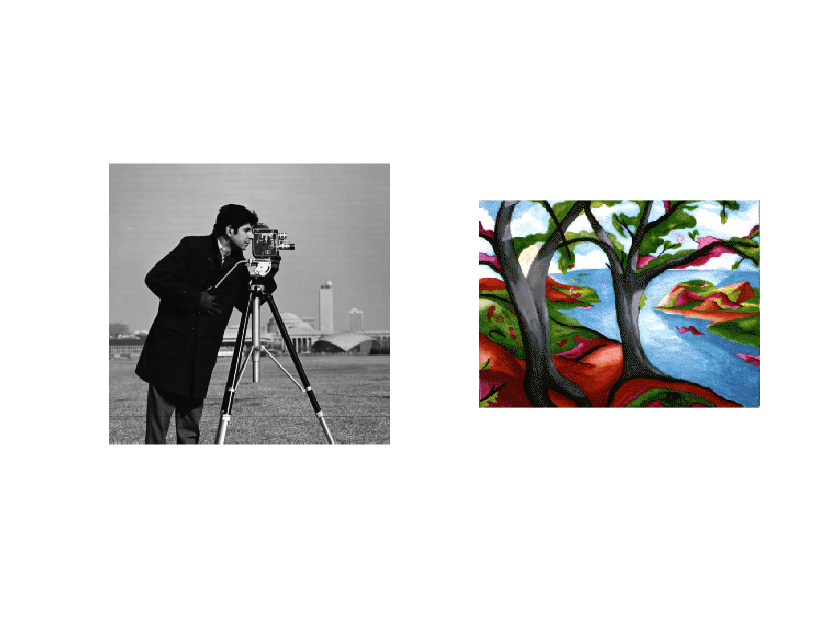

[x,map]=imread('trees.tif');
imshow(x,map)

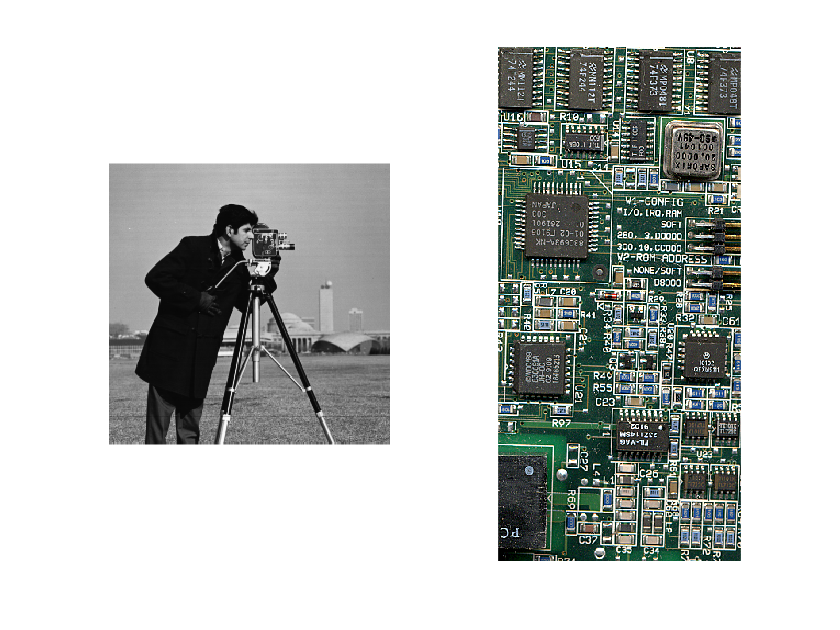

imshow('board.tif')

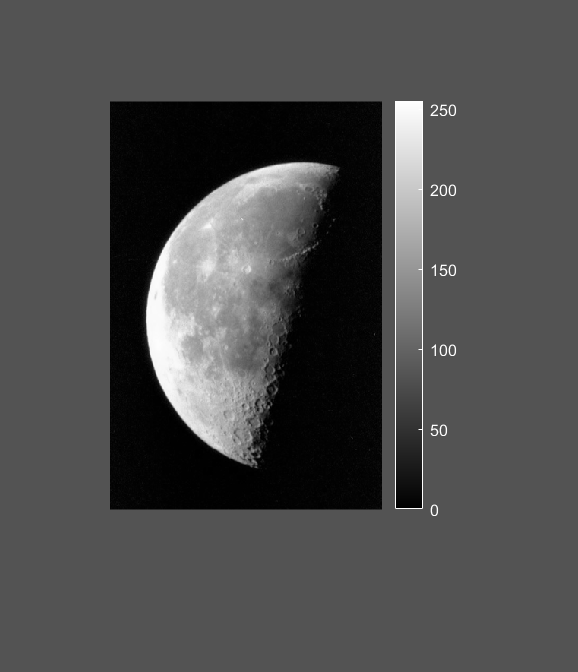

vals =      6     6     6
   207   207   207
   252   252   252


i=imread('moon.tif');
imshow(i)
colorbar
%vals=impixel

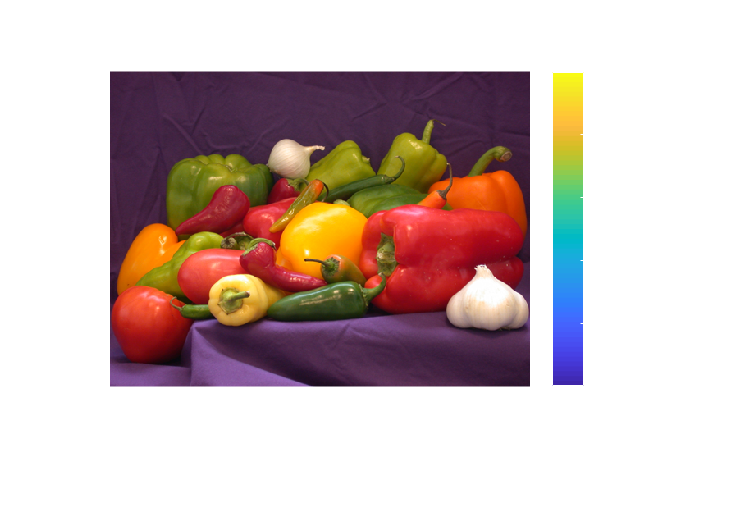

i1=imread('peppers.png');
figure
imshow(i1)
colorbar

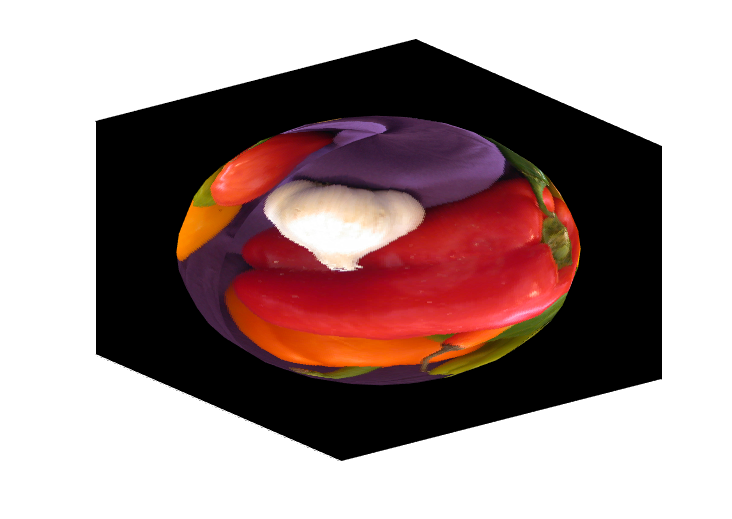

[x,y,z]=sphere;
i=imread('peppers.png');
warp(x,y,z,i)

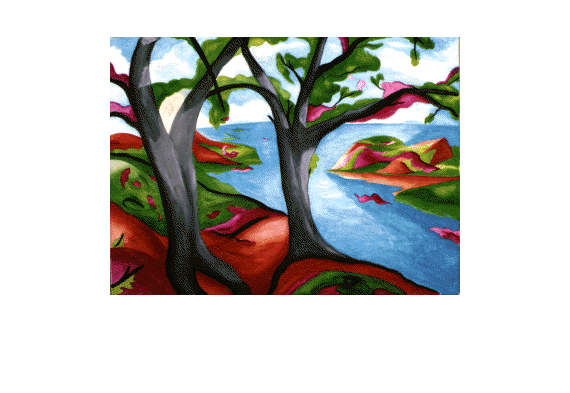

[x,map]=imread('trees.tif');
gmap=rgb2gray(map);
figure;imshow(x,map)

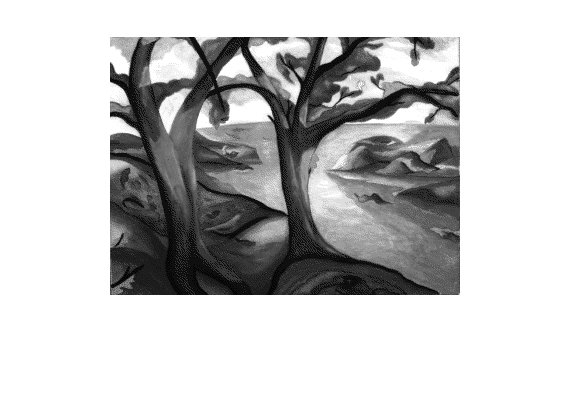

figure;imshow(x,gmap)

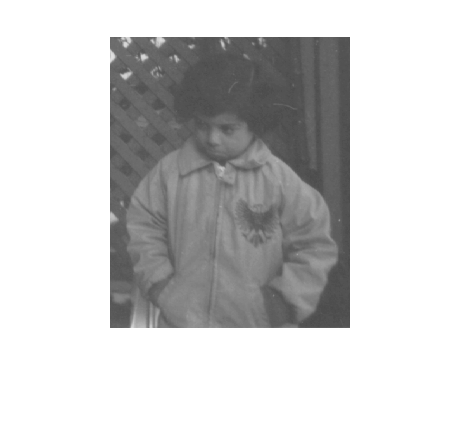

clc,clear all,close all;
i=imread('pout.tif');
figure,imshow(i);

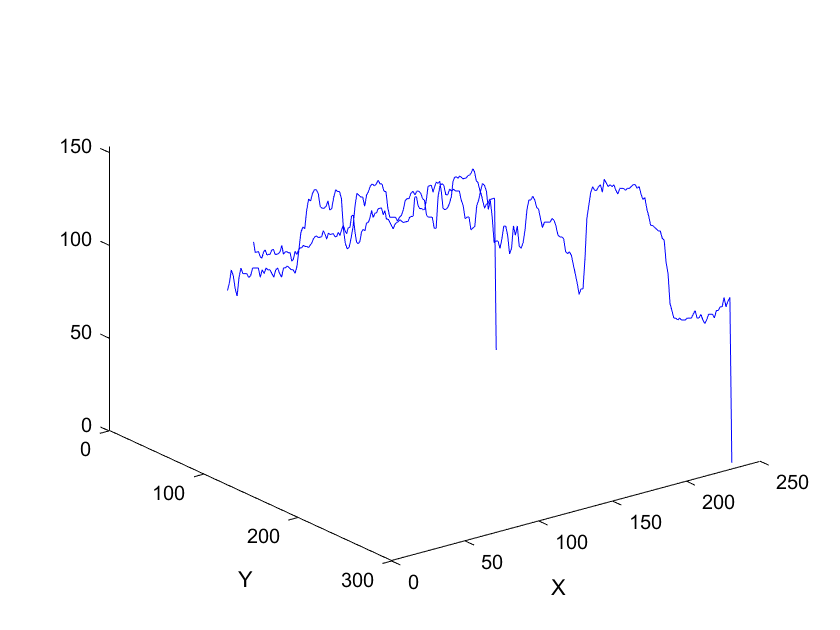

x=[19 427 416 77];
y=[96 462 37 33];
figure,improfile(i,x,y)

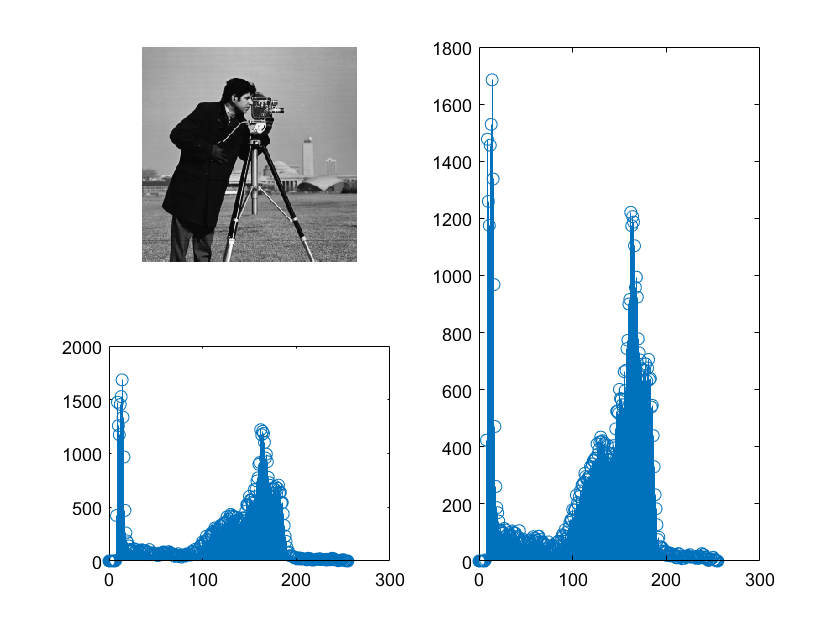

i=imread('cameraman.tif');
j=imadjust(i);%调整
%imcontour(i,120)
subplot(221)
imshow(i)
subplot(223)
[count,x]=imhist(i,256);%灰度直方图
stem(x,count)

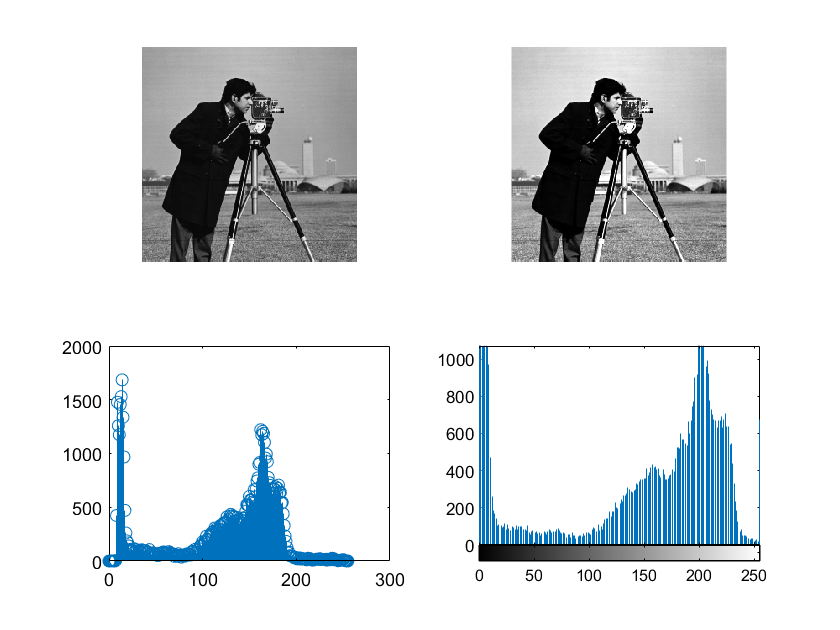

subplot(222)
imshow(j)
subplot(224)
imhist(j,256)

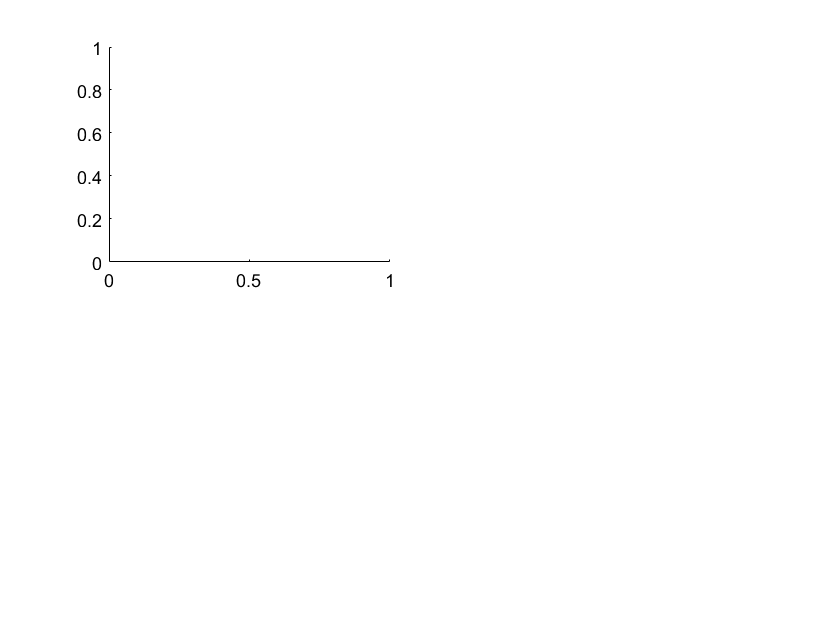

尝试将 SCRIPT image 作为函数执行:
D:\workspace\matlab\14\image.mlx

出错 images.internal.basicImageDisplay (line 24)
    hh = image(cdata, ...

出错 imshow (line 320)
hh = images.internal.basicImageDisplay(fig_handle,ax_handle,...

i=imread('pout.tif');
[j,t]=histeq(i);
subplot(221);imshow(i)

subplot(222);imshow(j)
subplot(223);plot((0:255)/255,t)
subplot(224);imhist(j,256)